# Wykres kołowy

Wykres kołowy przedstawia udział wartości danej kategorii w całości. [Więcej informacji na temat wykresów kołowych](https://www.mathworks.com/help/matlab/ref/pie.html).

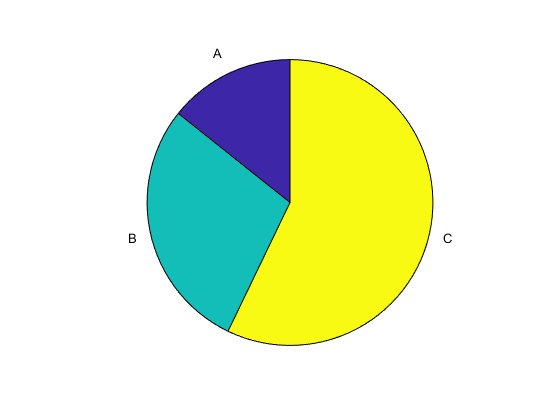

y = [1,2,4];
pie(y,["A","B","C"])

Jeśli przekazane zostaną wartości z zakresu 0-1 traktowane są one jako udział procentowy. Jeśli ich suma jest mniejsza od 1 to powstanie wycięty wykres kołowy.

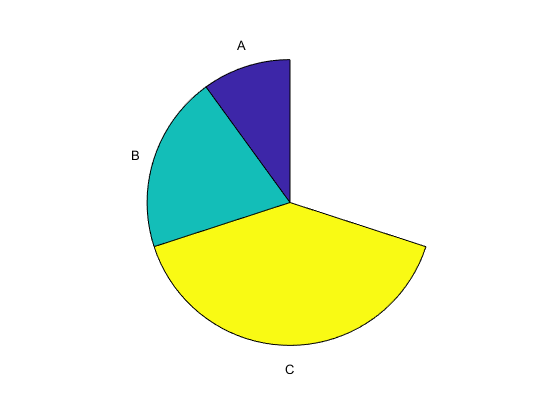

y = [0.1,0.2,0.4];
pie(y,["A","B","C"])

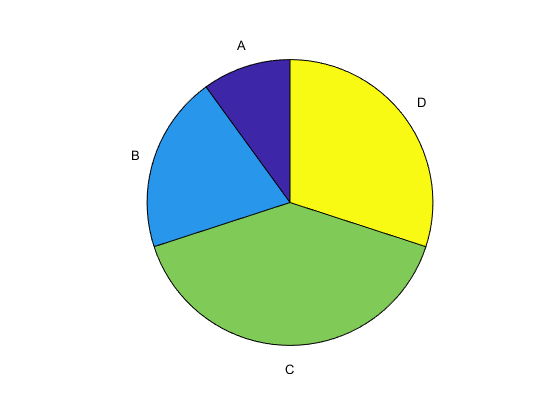

y = [0.1,0.2,0.4,0.3];
pie(y,["A","B","C","D"])

Jako drugi argument można przekazać wektor wartości 0/1, któe określają kategorie do wyróżnienia na wykresie. 1 oznacza wyróżnienie, 0 - brak wyróżnienia.

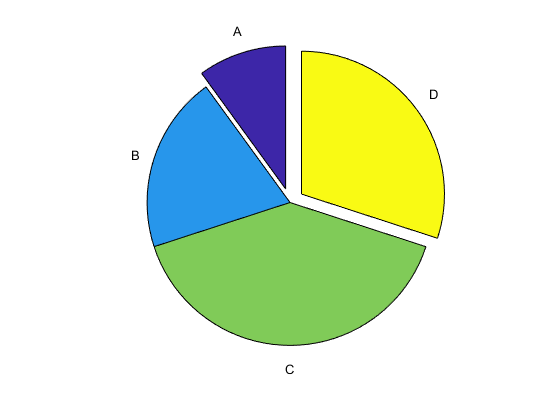

y = [0.1,0.2,0.4,0.3];
explode = [1, 0, 0, 1];
pie(y,explode,["A","B","C","D"])

Wykresy kołowe mogą być przydatne do pokazania różnic w udziale elementów w różnych kategoriach lub chwilach czasu. W tym celu można połączyc, wiele wykresów w jeden.

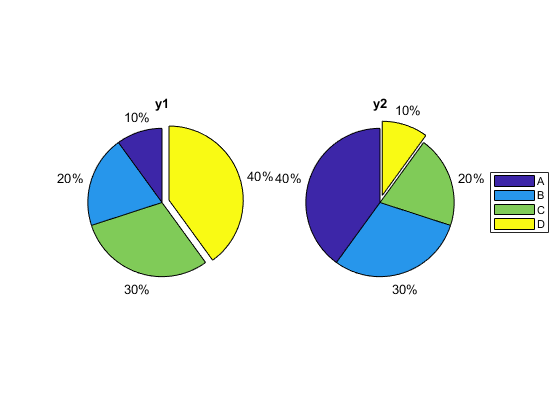

y1 = [1,2,3,4];
y2 = [4,3,2,1];
explode = [0,0,0,1];
newplot
t = tiledlayout(1,2,'TileSpacing','compact');
ax1 = nexttile;
pie(ax1,y1,explode)
title('y1')

ax2 = nexttile;
pie(ax2,y2,explode)
title('y2')

% Legenda
lgd = legend("A","B","C","D");
lgd.Layout.Tile = 'east';